clc; clear; close all;

% Simulated data
stress_ten = [5.3828e+04 6.6086e+04 1.3656e+05 1.6161e+05 1.6825e+05];
strain_ten = [0.00624792 0.01611160 0.07884710 0.10489400 0.11141400];
% Experimental data
stress_exp = [2.1776e+04 4.5303e+04 1.9632e+05 2.2483e+05 2.4773e+05];
strain_exp = [0.00670000 0.01600000 0.07810000 0.10430000 0.11030000];

% Theoretical data
young = 475e3;
mu = young/3;
strain = linspace(0,1,100);
J = 1;
lambda = 1 + strain;
% stress = mu*(lambda.^2 - 1./lambda)
% stress = mu*(lambda - 1./lambda.^2)
stress = (mu/J^(5/3))*(lambda.^2 - J./lambda);

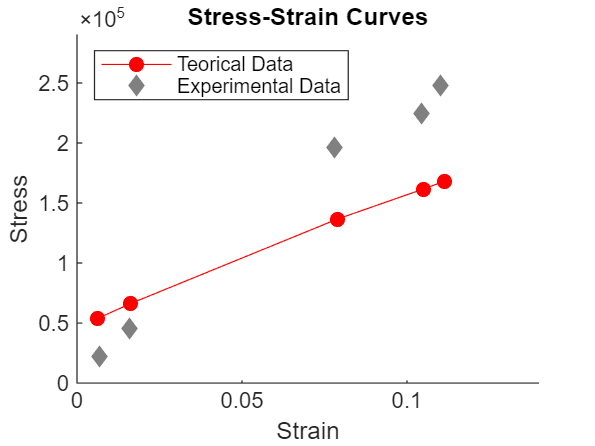

figure(1); 
hold on;
plot(strain_ten, stress_ten, 'o-', 'Color', 'red', 'MarkerFaceColor', 'red'); 
plot(strain_exp, stress_exp, 'd', 'Color', '#808080', 'MarkerFaceColor', '#808080'); 
xlim([0 0.14]); ylim([0 290e3]);
xlabel('Strain'); ylabel('Stress'); title('Stress-Strain Curves');
legend('Teorical Data', 'Experimental Data', 'Location', 'northwest');
hold off;